## [Support Vector Classifier](https://apmonitor.com/pds/index.php/Main/SupportVectorClassifier)

A support vector classifier is a type of machine learning model that can be used for classification tasks. Given a set of training examples, each labeled as belonging to one of two classes, the goal of the support vector classifier is to find a decision boundary that maximally separates the two classes.

Mathematically, we can represent the decision boundary as a linear function of the form $w^T x+b=0$, where *w* is a vector of weights, *x* is a vector of features, and *b* is a bias term. The decision boundary is the set of points that satisfy this equation. To find the decision boundary that maximally separates the two classes, we can solve the following optimization problem:


$$\min_{w,b} \frac{1}{2}{\left|w\right|}^2 +C\sum_{i=1}^n \max \left(0,1-y_i \;\left(w^T x_i +b\right)\right)$$


where *C* is a regularization parameter that controls the trade-off between maximizing the margin and minimizing the error, $y_i$ is the label of the *i*th training example (either 1 or -1), and $x_i$ is the corresponding feature vector. This optimization problem can be solved using quadratic programming.

Once the optimization problem has been solved and the decision boundary has been found, we can use it to make predictions on new data points. Given a new feature vector *x*, we can predict the class of the corresponding example by computing the value of the linear function $w^T x+b=0$ and comparing it to 0. If the value is positive, we predict that the example belongs to one class; if it is negative, we predict that the example belongs to the other class.

Support vector machine is a representation of the training data as points in space separated into categories by a clear gap that is as wide as possible. New examples are then mapped into that same space and predicted to belong to a category based on which side of the gap they fall. Use the [**Support Vector Machine (SVM) Explorer Dashboard**](https://dash.gallery/dash-svm/) to gain an intuitive understanding of classification and the parameters that influence the result.

**Advantages:** Effective in high dimensional spaces and uses a subset of training points in the decision function so it is also memory efficient.

**Disadvantages:** The algorithm does not directly provide probability estimates, these are calculated using a computationally expensive five-fold cross-validation.

**Optical Character Recognition with SVC**

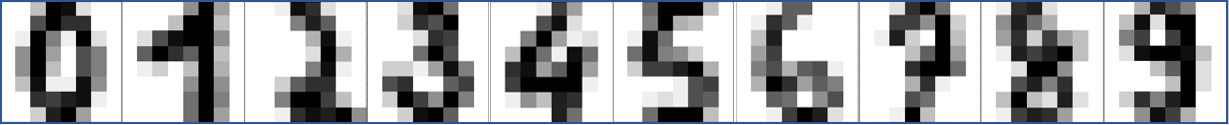

Optical character recognition (OCR) is a method used to convert images of text into machine-readable text. It is typically used to process scanned documents and recognize the text in the images. Support vector machines (SVMs) are a type of machine learning model that can be used for classification tasks. In the context of OCR, an SVM could be trained to recognize characters in images of text.

Dataset: [Data Sets for Deep Learning - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/deeplearning/ug/data-sets-for-deep-learning.html)

### **Import and Split the Data**

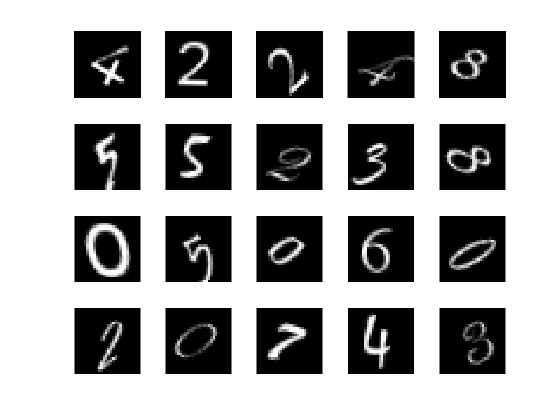

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files);

% Extract the images into a matrix
X_data = cell(n_samples, 1);
for i = 1:n_samples
    [X_data{i}] = deal(reshape(readimage(imds,i)',[1,28*28]));
end
X_data = cell2mat(X_data);

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);

% Split the data 50% training adn 50% testing
[trainInd,valInd,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

### Train and Evaluate the Classifier

% Create fit
classifier = fitcecoc(array2table(im2double(X_Train)),Y_Train,'Learners','svm');

% Evaluate the model performance on the test set
y_pred = predict(classifier,array2table(im2double(X_Test)));
accuracy = mean(y_pred == Y_Test);
fprintf("Accuracy: %.2f\n", accuracy);

Accuracy: 0.92


In this example, we load the dataset of images of handwritten digits, split the dataset into training and testing sets, and train an SVM classifier. We then evaluate the model's performance on the test set by computing the accuracy, which is the proportion of test images that the model correctly identifies.

### Test Individual Predictions

This is an example that shows a number from the test set and evaluates it with the Support Vector Classifier.

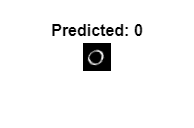

tbl = [array2table(im2double(X_Train)), array2table(Y_Train)];

% Select random nummber image
n = randi([0,n_samples],1);

% Get the prediction
reshape(readimage(imds,n)',[1,28*28]);
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));

% Display the image with the prediction
figure;
imshow(imds.Files{n})
titleText = "Predicted: " + string(yp);
title(titleText, 'FontSize', 12)